# Testing all images in DB to our dataset in DB1

clear TNM034
clear
clf
clc
clear livescript

files=dir('./DB1/*.jpg');
files =  {files.name};

% Test all files in a dataset against our dataset based on DB1
for file = files
    path = './DB1/' + string(file);
    im = imread(path);
    [id,value] = TNM034(im*1.1);
    fprintf('%s, %i, %.4f', string(file), id, value);
end

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights


db1_01.jpg, 1, 4.8565

Building dataset:
Dataset already exists, skipping.


db1_02.jpg, 2, 10.5592

Building dataset:
Dataset already exists, skipping.


db1_03.jpg, 3, 7.5572

Building dataset:
Dataset already exists, skipping.


db1_04.jpg, 4, 4.5081

Building dataset:
Dataset already exists, skipping.


db1_05.jpg, 5, 1.2942

Building dataset:
Dataset already exists, skipping.


db1_06.jpg, 6, 2.0072

Building dataset:
Dataset already exists, skipping.


db1_07.jpg, 7, 4.3208

Building dataset:
Dataset already exists, skipping.


db1_08.jpg, 8, 17.9533

Building dataset:
Dataset already exists, skipping.


db1_09.jpg, 9, 11.0964

Building dataset:
Dataset already exists, skipping.


db1_10.jpg, 10, 9.6552

Building dataset:
Dataset already exists, skipping.


db1_11.jpg, 11, 12.2208

Building dataset:
Dataset already exists, skipping.


db1_12.jpg, 12, 3.9434

Building dataset:
Dataset already exists, skipping.


db1_13.jpg, 13, 4.2533

Building dataset:
Dataset already exists, skipping.


db1_14.jpg, 14, 3.6683

Building dataset:
Dataset already exists, skipping.


db1_15.jpg, 16, 27.6608

Building dataset:
Dataset already exists, skipping.


db1_16.jpg, 16, 3.5222

Building dataset:
Creating image matrix
Image: db1_01.jpg 
Image: db1_02.jpg 
Image: db1_03.jpg 
Image: db1_04.jpg 
Image: db1_05.jpg 
Image: db1_06.jpg 
Image: db1_07.jpg 
Image: db1_08.jpg 
Image: db1_09.jpg 
Image: db1_10.jpg 
Image: db1_11.jpg 
Image: db1_12.jpg 
Image: db1_13.jpg 
Image: db1_14.jpg 
Image: db1_15.jpg 
Image: db1_16.jpg 
Creating mean face
Creating weights


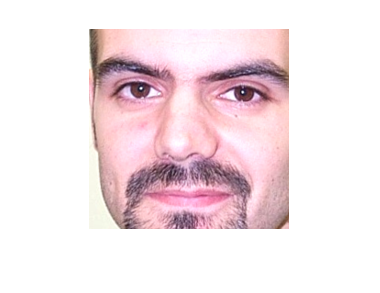

% [id,value] = TNM034(imread('./DB1/db1_08.jpg'));
[id,value] = TNM034(1.1*imread('./DB1/db1_08.jpg'));

fprintf('%s, %i, %f \n','', id, value);

, 8, 17.953346 


im = imread('./DB1/db1_14.jpg');

im = whitePatch(im);
im = normalizeRGBImage(im);
imshow(im)
im = faceMask(im);
imshow(im)

